clc
close all
clear all

% Import the data
% fn = 'D:\JHU BME MSE\FALL 23\ICM\ICM_FinalProject_Part_1\ADHD_ICM_random200.csv'; % change this to your local path
fn = 'ADHD_ICM_random200.xlsx'; % or put all working files in the same folder
data = readtable(fn,"VariableNamingRule",'preserve');

% Filter out the selected columns
columns_info = {'''Subject_ID''','''Gender''','''Age''','''Diagnosis'''};
columns_ROI = {'''PCC_R''','''PCC_L''','''dorsal_ACC_R''','''dorsal_ACC_L''','''rostral_ACC_R''','''rostral_ACC_L''','''subcallosal_ACC_R''','''subcallosal_ACC_L''','''subgenual_ACC_R''','''subgenual_ACC_L'''};
data_vol = data(:,[columns_info, columns_ROI]);

% Separate the patients into ADHD and normal groups
data_vol_ADHD = data_vol(string(data_vol.("'Diagnosis'"))=='''ADHD''',columns_ROI);
data_vol_normal = data_vol(string(data_vol.("'Diagnosis'"))=='''NORMAL''',columns_ROI);

%%%%% Compare whole volume of cingulate lobe of ADHD vs Normal
compare_vol = ["Whole cingulate lobe"];
allvol_ADHD = sum(table2array(data_vol_ADHD),2);
allvol_normal = sum(table2array(data_vol_normal),2);

p = stats(compare_vol, allvol_ADHD, allvol_normal, 0.05);

Whole cingulate lobe:
     Normality: false
     Wilcoxon rank-sum: p = 0.020602
Control 67720 (6.195850e+04 - 80830) 
ADHD 7.171150e+04 (64366 - 102027) 


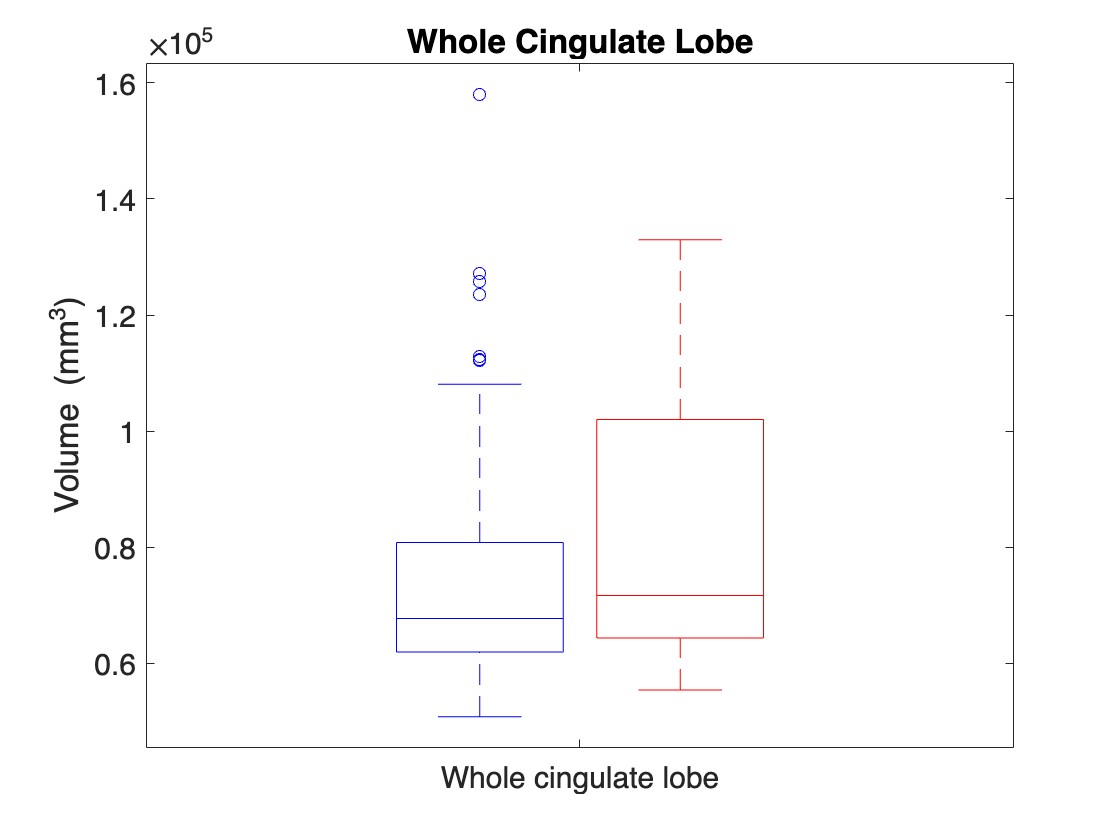

n = max([size(allvol_ADHD,1), size(allvol_normal,1)]);
plotgroups(allvol_ADHD, allvol_normal, n, compare_vol, "Whole Cingulate Lobe");


%%%%%% Compare volume of left / right cingulate lobe of ADHD vs Normal
compare_vol = ["Left cingulate lobe", "Right cingulate lobe"];
left_cols = columns_ROI(contains(columns_ROI, '_L'));
right_cols = columns_ROI(contains(columns_ROI, '_R'));

lcl_ADHD = table2array(data_vol_ADHD(:,left_cols));
rcl_ADHD = table2array(data_vol_ADHD(:,right_cols));

lcl_normal = table2array(data_vol_normal(:,left_cols));
rcl_normal = table2array(data_vol_normal(:,right_cols));

halfcl_ADHD = [sum(lcl_ADHD,2), sum(rcl_ADHD,2)];
halfcl_normal = [sum(lcl_normal,2), sum(rcl_normal,2)];

p = stats(compare_vol, halfcl_ADHD, halfcl_normal, 0.05);

Left cingulate lobe:
     Normality: false
     Wilcoxon rank-sum: p = 0.067339
Control 33010 (3.045250e+04 - 38189) 
ADHD 3.422650e+04 (3.113750e+04 - 4.773450e+04) 
Right cingulate lobe:
     Normality: false
     Wilcoxon rank-sum: p = 0.021286
Control 34593 (31762 - 41860) 
ADHD 37643 (3.303050e+04 - 54510) 


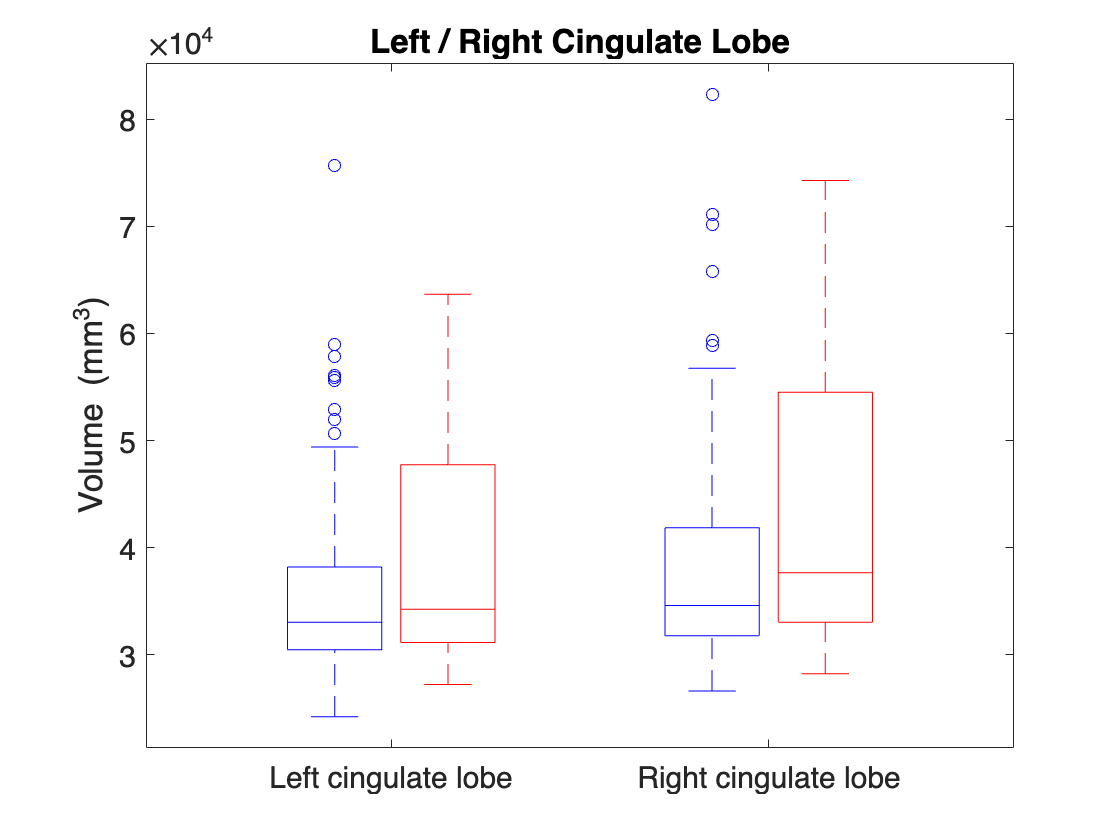

plotgroups(halfcl_ADHD, halfcl_normal, n, compare_vol, "Left / Right Cingulate Lobe")


%%%%%%% Comparing subregions
compare_vol = ["PCC", "dorsal ACC", "rostral ACC", "subcallosal ACC", "subgenual ACC"];
subregion_ADHD = lcl_ADHD + rcl_ADHD;
subregion_normal = lcl_normal + rcl_normal;
p = stats(compare_vol, subregion_ADHD, subregion_normal, 0.05);

PCC:
     Normality: false
     Wilcoxon rank-sum: p = 0.019261
Control 2.313850e+04 (21053 - 2.598950e+04) 
ADHD 24911 (2.216050e+04 - 2.955350e+04) 
dorsal ACC:
     Normality: false
     Wilcoxon rank-sum: p = 0.19686
Control 31497 (29198 - 36233) 
ADHD 3.317750e+04 (29603 - 4.900650e+04) 
rostral ACC:
     Normality: false
     Wilcoxon rank-sum: p = 0.19051
Control 7724 (6844 - 9724) 
ADHD 8.248500e+03 (6.913500e+03 - 1.395950e+04) 
subcallosal ACC:
     Normality: false
     Wilcoxon rank-sum: p = 2.6395
Control 1046 (8.765000e+02 - 1.214500e+03) 
ADHD 1010 (8.745000e+02 - 1205) 
subgenual ACC:
     Normality: false
     Wilcoxon rank-sum: p = 0.50387
Control 4.037500e+03 (3603 - 5.605500e+03) 
ADHD 4433 (3641 - 8.075500e+03) 


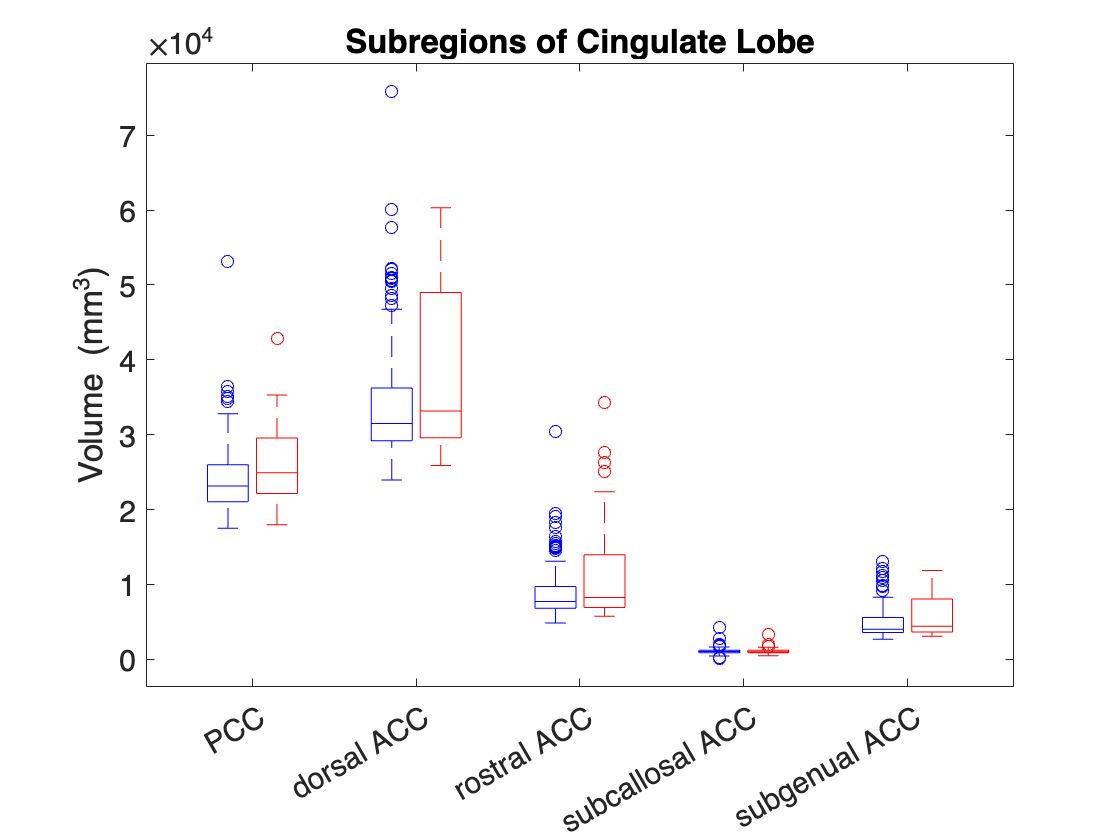

plotgroups(subregion_ADHD, subregion_normal, n, compare_vol, "Subregions of Cingulate Lobe")


% Compare volume of each subregion, left and right, of ADHD vs Normal
% NOTE: values > 1 are okay due to the Bonferroni correction
p = stats(string(columns_ROI), table2array(data_vol_ADHD), table2array(data_vol_normal), 0.05);

'PCC_R':
     Normality: false
     Wilcoxon rank-sum: p = 0.031145
Control 1.281450e+04 (11491 - 1.379550e+04) 
ADHD 1.381650e+04 (1.209650e+04 - 1.569750e+04) 
'PCC_L':
     Normality: false
     Wilcoxon rank-sum: p = 0.058218
Control 10330 (9364 - 1.206350e+04) 
ADHD 11573 (9.888500e+03 - 1.372050e+04) 
'dorsal_ACC_R':
     Normality: false
     Wilcoxon rank-sum: p = 0.19553
Control 1.533150e+04 (1.418250e+04 - 1.847350e+04) 
ADHD 16585 (1.451750e+04 - 26143) 
'dorsal_ACC_L':
     Normality: false
     Wilcoxon rank-sum: p = 1.073
Control 1.626350e+04 (1.495050e+04 - 1.879650e+04) 
ADHD 16683 (14872 - 23057) 
'rostral_ACC_R':
     Normality: false
     Wilcoxon rank-sum: p = 0.1042
Control 3949 (3372 - 5132) 
ADHD 4.269500e+03 (3610 - 8.055500e+03) 
'rostral_ACC_L':
     Normality: false
     Wilcoxon rank-sum: p = 2.8574
Control 3.879500e+03 (3440 - 4560) 
ADHD 4051 (3.407500e+03 - 6169) 
'subcallosal_ACC_R':
     Normality: false
     Wilcoxon rank-sum: p = 3.7489
Control 5.6150